# Color transfer between images

## Color transfer will transfer the color tone from the source image to the target image.

Step 1: Input images are a source and a target image.  Display both images.

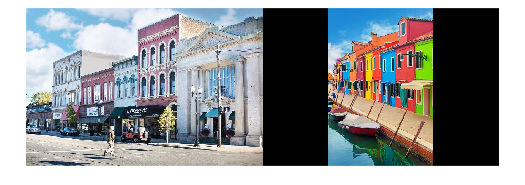

% Target img
block_img = imread('city_block1.png');

% Source img
colorful_img = imread('colorful_town1.png');
[r,c,ch] = size(colorful_img);

montage({block_img, colorful_img});

Step 2: Convert RGB to lαβ color space.  Images have size [m n 3].  You can use function "reshape" to change the size to [m*n  3]. So that we can multiply with other matrices.

% Reshape (get matrix size [m*n 3])
% ** Aj said that max will replace the value when it's 0, then it will set a
% very small number like 1/255 instead**
BLOCK = reshape(max(im2double(block_img), 1/255), [], 3);
COL = reshape(max(im2double(colorful_img), 1/255), [], 3);

% Finding lms
Block_lms = [0.3811 0.5783 0.0402; 0.1967 0.7244 0.0782; 0.0241 0.1288 0.8444] * BLOCK.';
Color_lms = [0.3811 0.5783 0.0402; 0.1967 0.7244 0.0782; 0.0241 0.1288 0.8444] * COL.';

% Finding LMS (take log to lms)
Block_LMS = log10(Block_lms);
Color_LMS = log10(Color_lms);

% Finding lαβ
Block_lab = [(1/sqrt(3)) 0 0; 0 (1/sqrt(6)) 0; 0 0 (1/sqrt(2))] * [1 1 1; 1 1 -2; 1 -1 0] * Block_LMS;
Color_lab = [(1/sqrt(3)) 0 0; 0 (1/sqrt(6)) 0; 0 0 (1/sqrt(2))] * [1 1 1; 1 1 -2; 1 -1 0] * Color_LMS;

% Fill in NaN and inf with 0 (because it makes mean and std NaN ;-;)
% Block_lab(isnan(Block_lab)) = 0;
% Block_lab(Block_lab == -inf) = 0;

% Color_lab(isnan(Color_lab)) = 0;
% Color_lab(Color_lab == -inf) = 0;

Step 3: Compute the mean and standard deviation of each of the lαβ channels for the source and target images.

% Finding mean (μ) of each lαβ channels
Block_meanl = mean2(Block_lab(1,:));
Block_meana = mean2(Block_lab(2,:));
Block_meanb = mean2(Block_lab(3,:));
% Block_mean = cat(3, Block_meanl, Block_meana, Block_meanb);

Color_meanl = mean2(Color_lab(1,:));
Color_meana = mean2(Color_lab(2,:));
Color_meanb = mean2(Color_lab(3,:));
% Color_mean = cat(3, Color_meanl, Color_meana, Color_meanb);

% Finding standard deviation (σ) of each lαβ channels
Block_stdl = std2(Block_lab(1,:));
Block_stda = std2(Block_lab(2,:));
Block_stdb = std2(Block_lab(3,:));
% Block_std = cat(3, Block_stdl, Block_stda, Block_stdb);

Color_stdl = std2(Color_lab(1,:));
Color_stda = std2(Color_lab(2,:));
Color_stdb = std2(Color_lab(3,:));
% Color_std = cat(3, Color_stdl, Color_stda, Color_stdb);

Step 4: Subtract the mean of the lαβ channels of the target image from target channels.

targ_l = Color_lab(1,:) - Color_meanl;
targ_a = Color_lab(2,:) - Color_meana;
targ_b = Color_lab(3,:) - Color_meanb;
% BLOCK = BLOCK - Block_mean;

Step 5: Scale the target channels by the ratio of the standard deviation of the source divided by the standard deviation of the target, multiplied by the target channels.

targ_l = (Block_stdl / Color_stdl) * targ_l;
targ_a = (Block_stda / Color_stda) * targ_a;
targ_b = (Block_stdb / Color_stdb) * targ_b;
% BLOCK = (Color_std ./ Block_std) .* BLOCK;

Step 6: Add in the means of the lαβ channels for the source.

targ_l = targ_l + Block_meanl

targ_l =    -0.2741   -0.2679   -0.2679   -0.2679   -0.2618   -0.2618   -0.2618   -0.2618   -0.2618   -0.2618   -0.2618   -0.2618   -0.2618   -0.2645   -0.2645   -0.2584   -0.2584   -0.2584   -0.2506   -0.2567   -0.2567   -0.2584   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2524   -0.2464   -0.2464   -0.2405   -0.2405   -0.2405   -0.2391   -0.2405   -0.2464   -0.2464   -0.2464   -0.2405   -0.2346   -0.2346   -0.2405   -0.2405   -0.2405   -0.2405   -0.2405


targ_a = targ_a + Block_meana

targ_a =    -0.1037   -0.1032   -0.1032   -0.1032   -0.1028   -0.1028   -0.1028   -0.1028   -0.1028   -0.1028   -0.1028   -0.1028   -0.1028   -0.1020   -0.1020   -0.1015   -0.1015   -0.1015   -0.1008   -0.1012   -0.1012   -0.1015   -0.1011   -0.1011   -0.1011   -0.1011   -0.1011   -0.1011   -0.1011   -0.1011   -0.1011   -0.1011   -0.1006   -0.1006   -0.1002   -0.1002   -0.1002   -0.0999   -0.1002   -0.1006   -0.1006   -0.1006   -0.1002   -0.0998   -0.0998   -0.1002   -0.1002   -0.1002   -0.1002   -0.1002


targ_b = targ_b + Block_meanb

targ_b =    -0.0235   -0.0233   -0.0233   -0.0233   -0.0231   -0.0231   -0.0231   -0.0231   -0.0231   -0.0231   -0.0231   -0.0231   -0.0231   -0.0231   -0.0231   -0.0229   -0.0229   -0.0229   -0.0229   -0.0231   -0.0231   -0.0229   -0.0227   -0.0227   -0.0227   -0.0227   -0.0227   -0.0227   -0.0227   -0.0227   -0.0227   -0.0227   -0.0225   -0.0225   -0.0224   -0.0224   -0.0224   -0.0222   -0.0224   -0.0225   -0.0225   -0.0225   -0.0224   -0.0222   -0.0222   -0.0224   -0.0224   -0.0224   -0.0224   -0.0224


% BLOCK = BLOCK + Color_mean;

Step 7: Convert lαβ back to RGB color space.

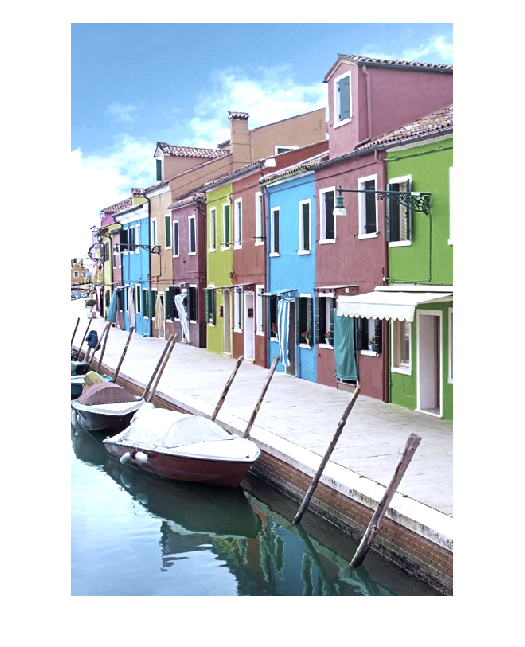

targ_lab = vertcat(targ_l, targ_a, targ_b);

% Reshape to original size
% rgb = reshape(rgb, [r c ch]);

% lab = reshape(max(im2double(rgb), 1/255), [], 3);

LMS = [1 1 1; 1 1 -1; 1 -2 0] * [(sqrt(3)/3) 0 0; 0 (sqrt(6)/6) 0; 0 0 (sqrt(2)/2)] * targ_lab;

% Invert log scale
lms = power(10,LMS);

final_rgb = [4.4679 -3.5873 0.1193; -1.2186 2.3809 -0.1624; 0.0497 -0.2439 1.2045] * lms;

% % Separate each channel
R = final_rgb(1,:);
G = final_rgb(2,:);
B = final_rgb(3,:);

res = cat(3, R, G, B);

res = reshape(res, [r c ch]);

imshow(res);